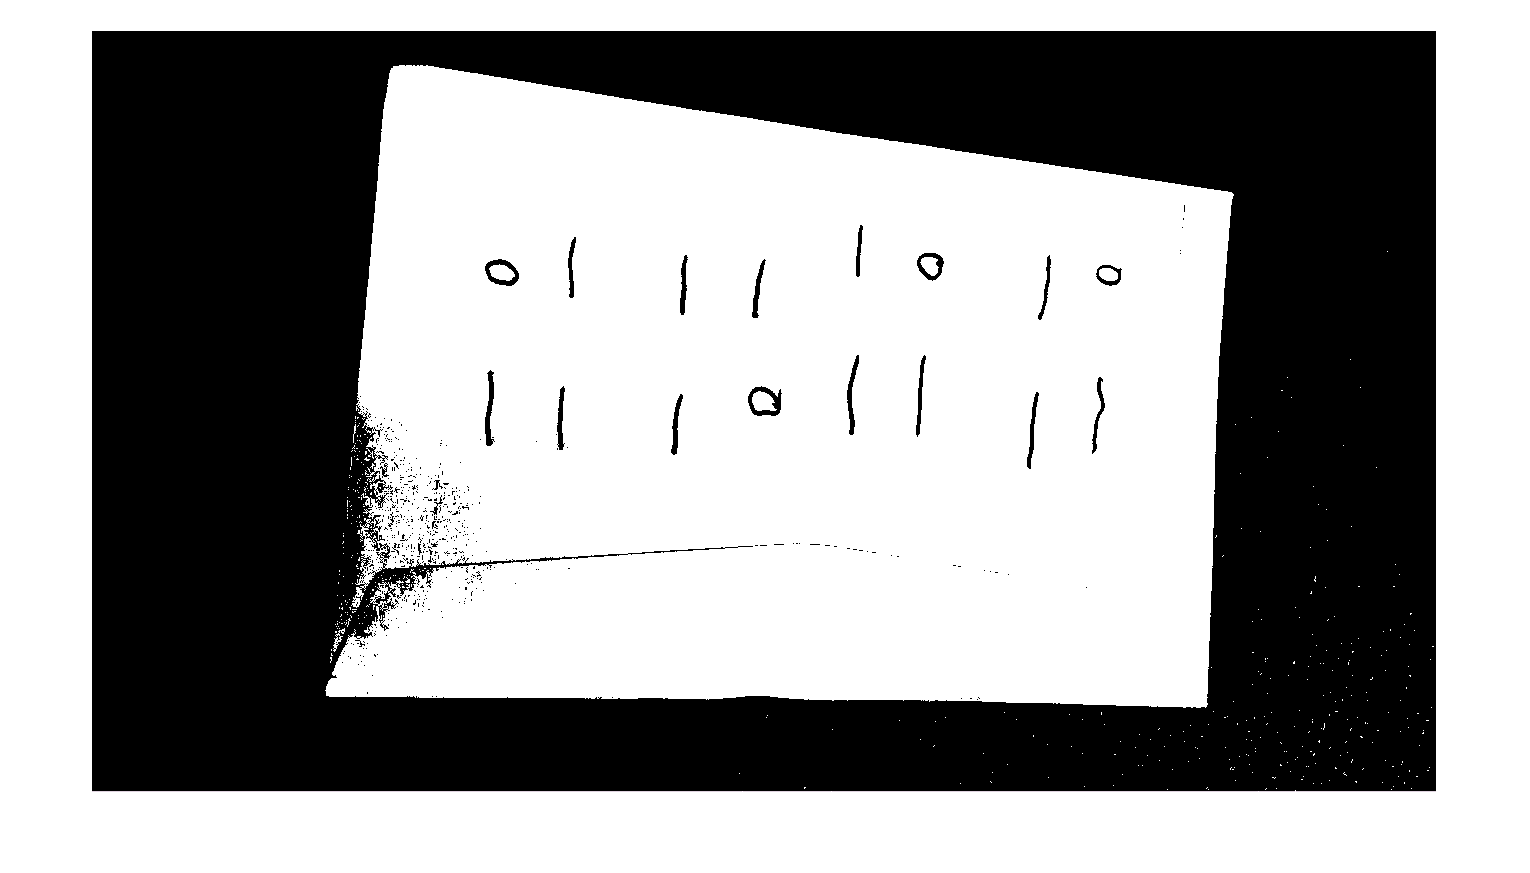

clear all;
clc;
close all;

I = im2bw(rgb2gray(imread('test2.jpg')),.45);
imshow(I);

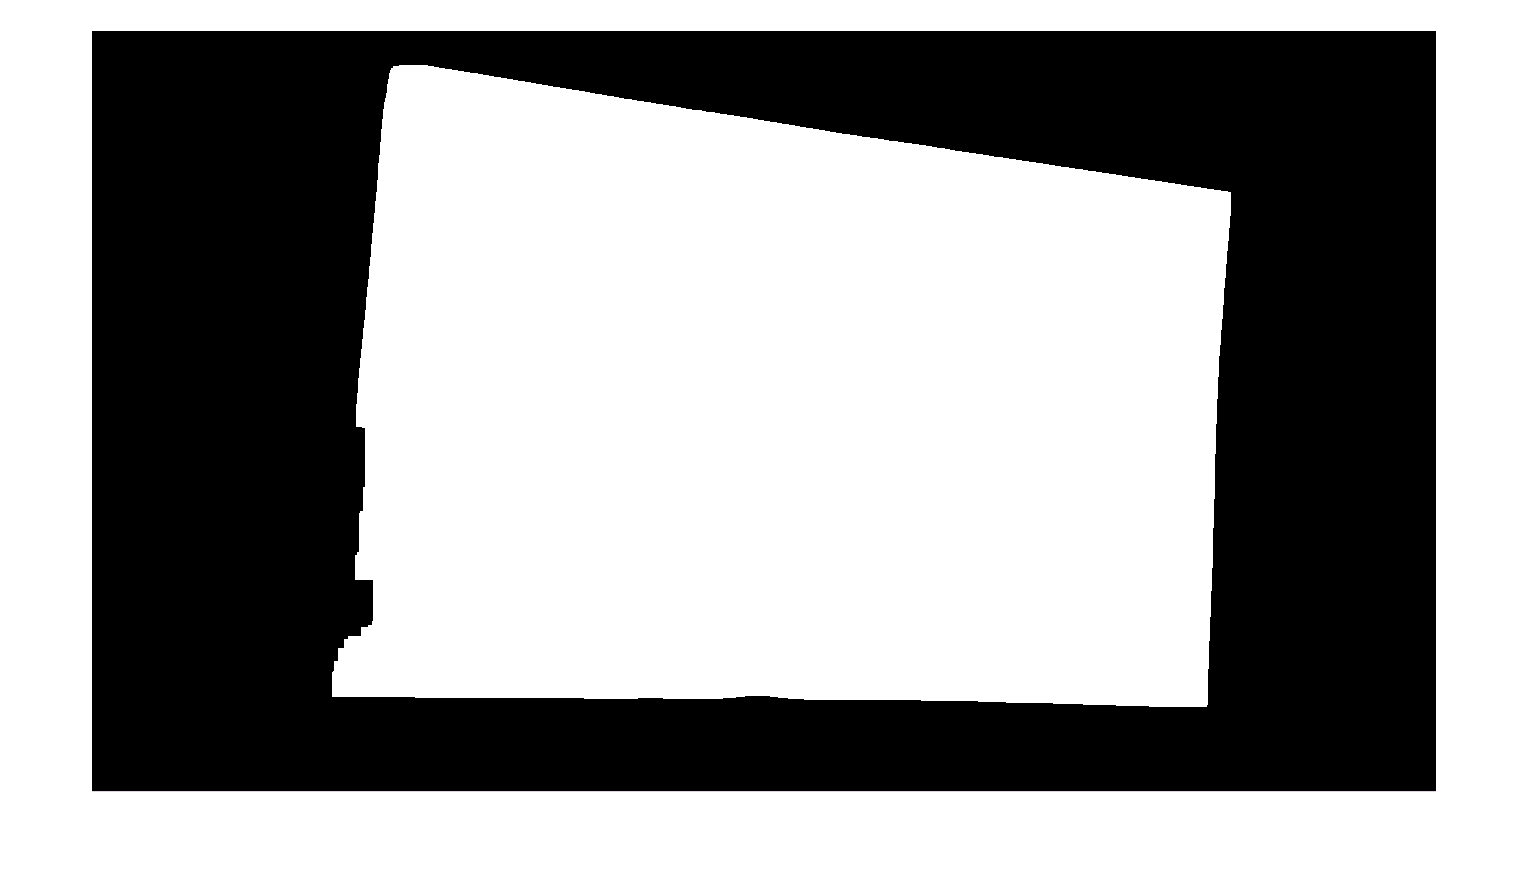

se = strel('square',10);

I = imclose(I,se);
I = imopen(I,se);

se = strel('square',40);
I = imopen(I,se);

se = strel('square',45);
I = imclose(I,se);
imshow(I);

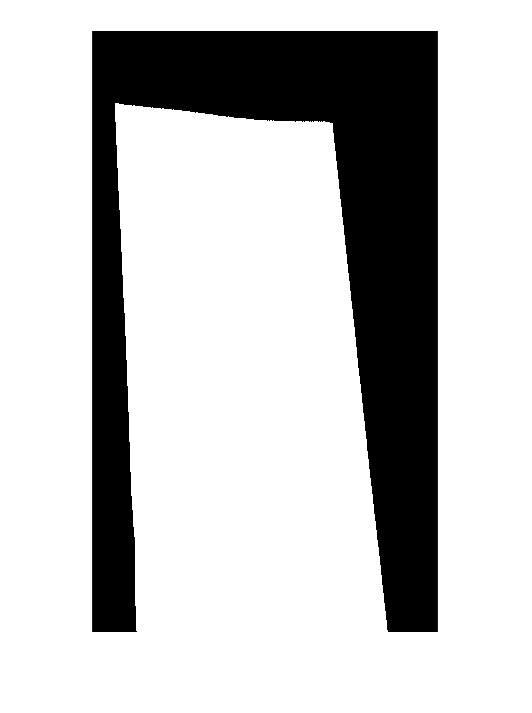


%%Test Harris
[r,c] = getcorners(I,'h',10,.1,.001);

M2 = extremeCorners([r,c]);



imshow(align(I,M2));